# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with the following properties:

Run the script to create the layers in the workspace variable `net`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 15-Jul-2024 13:04:11

clc
clear

# Loading dataset & dividing into Training, Validation and testing datasets

imds = imageDatastore("C:\AcousticDataset\Journal 2\ShipsEar\ShipsEAR_data","IncludeSubfolders",true,"LabelSource","foldernames");


classNames = categories(imds.Labels);
numClasses = numel(categories(imds.Labels));

[imdsTrain,imdsValidation] = splitEachLabel(imds,0.7,'randomized');

## Create dlnetwork

Create the dlnetwork variable to contain the network layers.

net = dlnetwork;

## Add Layer Branches

Add branches to the dlnetwork. Each branch is a linear array of layers.

tempNet = imageInputLayer([50 4400 1],"Name","imageinput");
net = addLayers(net,tempNet);

tempNet = resize2dLayer("Name","resize-output-size","GeometricTransformMode","half-pixel","Method","nearest","NearestRoundingMode","round","OutputSize",[50 400]);
net = addLayers(net,tempNet);

tempNet = [
    crop2dLayer([4001 1],"Name","crop2d")
    convolution2dLayer([3 3],8,"Name","conv_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([2 2],"Name","maxpool_1","Stride",[2 2])
    convolution2dLayer([5 5],16,"Name","conv_2","Padding","same")
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_2")
    maxPooling2dLayer([2 2],"Name","maxpool_2","Stride",[2 2])
    convolution2dLayer([7 7],32,"Name","conv_3","Padding","same")
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_3")
    fullyConnectedLayer(5,"Name","fc")
    softmaxLayer("Name","softmax")];
net = addLayers(net,tempNet);

% clean up helper variable
clear tempNet;

net = connectLayers(net,"imageinput","resize-output-size");
net = connectLayers(net,"imageinput","crop2d/in");
net = connectLayers(net,"resize-output-size","crop2d/ref");
net = initialize(net);

analyzeNetwork(net);

options = trainingOptions("sgdm", ...
    InitialLearnRate=0.001, ...
    MaxEpochs=10, ...
    MiniBatchSize=128, ...
    ExecutionEnvironment="gpu", ...
    Shuffle="every-epoch", ...
    ValidationData=imdsValidation, ...
    ValidationFrequency=10, ...
    ValidationPatience=10, ...
    Plots="training-progress", ...
    Metrics=["accuracy"], ...
    Verbose=false);

# Training Network

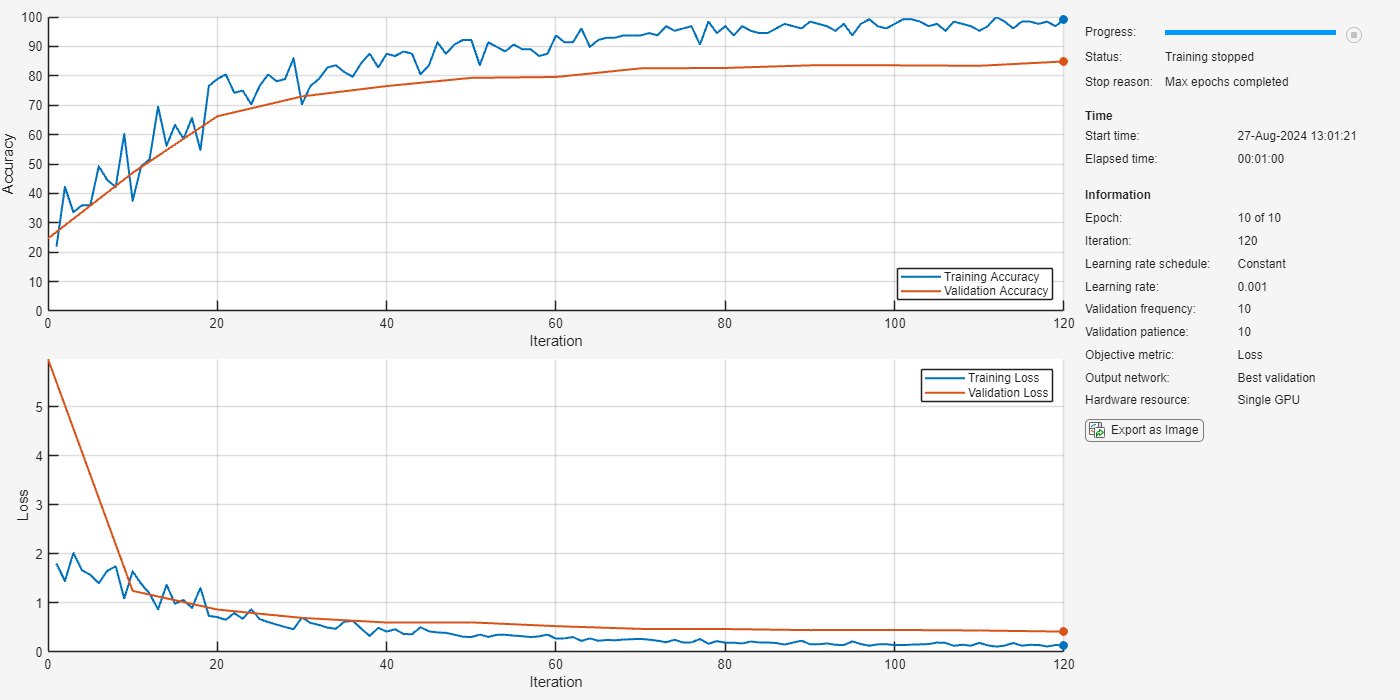

[net2,info] = trainnet(imdsTrain,net,"crossentropy",options);


% classNames = categories(imdsTest.Labels);
% numClasses = numel(categories(imds.Labels));
% 
% YTest = minibatchpredict(net2,imdsTest);
% YTest = onehotdecode(YTest,classNames,2);
% 
% figure
% TTest = imdsTest.Labels;
% cm = confusionchart(TTest,YTest,'Normalization','row-normalized');
% cm.RowSummary = 'row-normalized';
% cm.ColumnSummary = 'column-normalized';

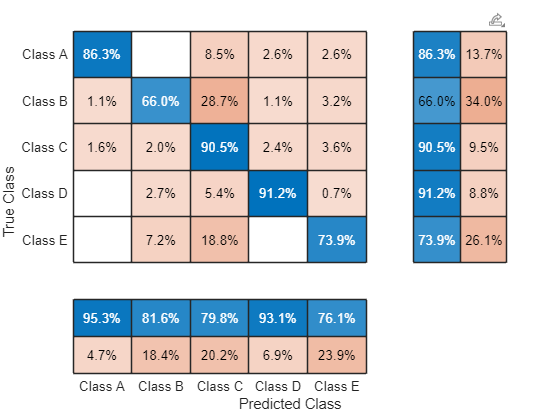

classNames = categories(imdsValidation.Labels);
numClasses = numel(categories(imds.Labels));

YTest = minibatchpredict(net2,imdsValidation);
YTest = onehotdecode(YTest,classNames,2);

figure
TTest = imdsValidation.Labels;
cm = confusionchart(TTest,YTest,'Normalization','row-normalized');
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';

% 
% % % imds2 = imageDatastore("D:\CODES\Machine Learning\48x3072 Gray\dataseet SS07","IncludeSubfolders",true,"LabelSource","foldernames");
% % % [imdsTrain2,imdsValidation2,imdsTest2] = splitEachLabel(imds,0.1,0.1,0.8,'randomized');
% % 
% % results_train = table2array(info.TrainingHistory);
% % results_val = table2array(info.ValidationHistory);
% % 
% % % Figures of Results
% % figure
% % plot(results_train(1:30:end,1) , results_train(1:30:end,5),'-o', results_val(:,1) , results_val(:,3),'-o')
% % title('Accuracy')
% % legend({'Training','validaiton'})
% % xlabel('Iterations')
% % ylabel('Accuracy')
% % 
% % figure
% % plot(results_train(1:30:end,1) , results_train(1:30:end,4),'-o', results_val(:,1) , results_val(:,2),'-o')
% % title('Loss')
% % legend({'Training','validaiton'})
% % xlabel('Loss')
% % ylabel('Accuracy')
% % figure
% % plot(results_train(1:30:end,1) , results_train(1:30:end,6),'-o', results_val(:,1) , results_val(:,4),'-o')
% % title('Fscore')
% % legend({'Training','validaiton'})
% % xlabel('FScore','FontWeight','bold')
% % ylabel('Accuracy','FontWeight','bold')


% Performance Measurements
confusionMat =cm.NormalizedValues

confusionMat =    0.863247863247863                   0   0.085470085470085   0.025641025641026   0.025641025641026
   0.010638297872340   0.659574468085106   0.287234042553192   0.010638297872340   0.031914893617021
   0.015810276679842   0.019762845849802   0.905138339920949   0.023715415019763   0.035573122529644
                   0   0.027027027027027   0.054054054054054   0.912162162162162   0.006756756756757
                   0   0.072463768115942   0.188405797101449                   0   0.739130434782609


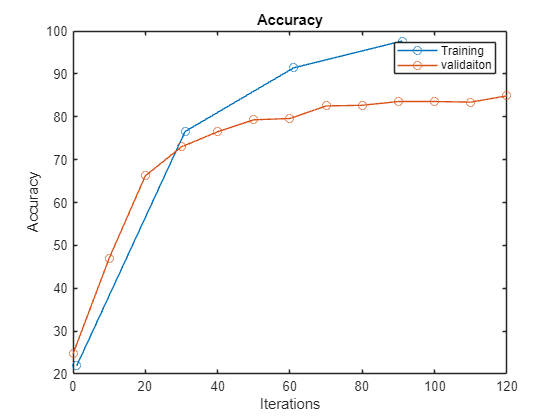

results_train = table2array(info.TrainingHistory);
results_val = table2array(info.ValidationHistory);

% Figures of Results
figure
plot(results_train(1:30:end,1) , results_train(1:30:end,5),'-o', results_val(:,1) , results_val(:,3),'-o')
title('Accuracy')
legend({'Training','validaiton'})
xlabel('Iterations')
ylabel('Accuracy')

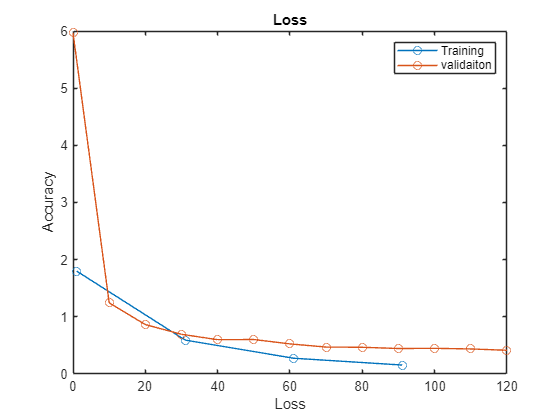

figure
plot(results_train(1:30:end,1) , results_train(1:30:end,4),'-o', results_val(:,1) , results_val(:,2),'-o')
title('Loss')
legend({'Training','validaiton'})
xlabel('Loss')
ylabel('Accuracy')

[Result_special,ReferenceResult] = multiclass_metrics_special(confusionMat)

Result_special = struct with fields:
                          Accuracy: 0.815850653639738
                             Error: 0.184149346360262
                            Recall: 0.815850653639738
                       Specificity: 0.953962663409934
                         Precision: 0.846351250062389
                 FalsePositiveRate: 0.046037336590066
                          F1_score: 0.820473970651684
    MatthewsCorrelationCoefficient: 0.783022516100880
                             Kappa: 0.424533292624181


ReferenceResult = struct with fields:
                  AccuracyOfSingle: [5×1 double]
                     ErrorOfSingle: [5×1 double]
                   AccuracyInTotal: [5×1 double]
                      ErrorInTotal: [5×1 double]
                            Recall: [5×1 double]
                       Specificity: [5×1 double]
                         Precision: [5×1 double]
                 FalsePositiveRate: [5×1 double]
                          F1_score: [5×1 double]
    MatthewsCorrelationCoefficient: [5×1 double]
                             Kappa: [5×1 double]
                      TruePositive: [5×1 double]
                     FalsePositive: [5×1 double]
                     FalseNegative: [5×1 double]
                      TrueNegative: [5×1 double]


function [Result,ReferenceResult] = multiclass_metrics_special(confMatrix)
            
%%***********************************************************************%
%*                         Multiclass metrics                           *%
%*        Finds the multiclss metrics provided a confusion matrix.      *%
%*                                                                      *%
%* Code author: Preetham Manjunatha                                     *%
%* Github link: https://github.com/preethamam                           %*
%* Date: 11/24/2021                                                     *%
%************************************************************************%
%
%************************************************************************%
%     %confusion matrix for multiple class start
%     %Inputs-1.Actual Class Labels,2.Predict Class Labels and 3.Display if need
%     %Outputs
%     
%     %1.Result-Struct Over all output Which has follwing
%     %2.RefereceResult indidual output Which has follwing
%     %%%%%%%%1.acuuracy
%     %%%%%%%%2.error
%     %%%%%%%%3.Recall (Recall or True positive rate)
%     %%%%%%%%4.Specificity
%     %%%%%%%%5.Precision
%     %%%%%%%%6.FPR-False positive rate
%     %%%%%%%%7.F_score
%     %%%%%%%%8.MCC-Matthews correlation coefficient
%     %%%%%%%%9.kappa-Cohen's kappa
% 
%     %%Original Developer Mr.Abbas Manthiri S
%     %%Date  25-12-2016
%     %%Mail Id: abbasmanthiribe@gmail.com
%     %%http://www.dataschool.io/simple-guide-to-confusion-matrix-terminology/
%     %%https://en.wikipedia.org/wiki/Confusion_matrix
%     
%     %%Modified by Preetham Manjunatha
%     %%Date  02-03-2020
%     %%Note: Fixed Abbas written code where the NaN and Inf values were
%     not considered while performaing the class average.
% 
%     % clc
%     % clear all
%     % close all
%     % %%Multiclass or two class
%     % [Result,RefereceResult] = multiclass_metrics(confMatrix)
            
    % Size of confusion matrix
    [row,col]=size(confMatrix);
    if row~=col
        error('Confusion matrix dimention is wrong')
    end
    
    % Number of classes
    n_class=row;
    
    % Find TP, FN, FP and TN
    switch n_class
        case 2
            TP=confMatrix(1,1);
            FN=confMatrix(1,2);
            FP=confMatrix(2,1);
            TN=confMatrix(2,2);
        otherwise
            TP=zeros(1,n_class);
            FN=zeros(1,n_class);
            FP=zeros(1,n_class);
            TN=zeros(1,n_class);
            for i=1:n_class
                TP(i)=confMatrix(i,i);
                FN(i)=sum(confMatrix(i,:))-confMatrix(i,i);
                FP(i)=sum(confMatrix(:,i))-confMatrix(i,i);
                TN(i)=sum(confMatrix(:))-TP(i)-FP(i)-FN(i);
            end
    end
            
    %% Calulations
    %1.P-Positive
    %2.N-Negative
    %3.acuuracy
    %4.error
    %5.Recall (Recall or True positive rate)
    %6.Specificity
    %7.Precision
    %8.FPR-False positive rate
    %9.F_score
    %10.MCC-Matthews correlation coefficient
    %11.kappa-Cohen's kappa
    P=TP+FN;
    N=FP+TN;
    switch n_class
        case 2
            accuracy=(TP+TN)/(P+N);
            Error=1-accuracy;
            Result.Accuracy=(accuracy);
            Result.Error=(Error);
        otherwise
            accuracy=(TP)./(P+N);
            Error=(FP)./(P+N);
            Result.Accuracy=sum(accuracy);
            Result.Error=sum(Error);
    end
    
    ReferenceResult.AccuracyOfSingle=(TP ./ P)';
    ReferenceResult.ErrorOfSingle=1-ReferenceResult.AccuracyOfSingle;
    Recall=TP./P;
    Specificity=TN./N;
    Precision=TP./(TP+FP);
    FPR=1-Specificity;
    beta=1;
    F1_score=( (1+(beta^2))*(Recall.*Precision) ) ./ ( (beta^2)*(Precision+Recall) );
    MCC=[( TP.*TN - FP.*FN ) ./ ( ( (TP+FP).*P.*N.*(TN+FN) ).^(0.5) );...
        ( FP.*FN - TP.*TN ) ./ ( ( (TP+FP).*P.*N.*(TN+FN) ).^(0.5) )] ;
    MCC=max(MCC);
    
    %Kappa Calculation BY 2x2 Matrix Shape
    pox=sum(accuracy);
    Px=sum(P);TPx=sum(TP);FPx=sum(FP);TNx=sum(TN);FNx=sum(FN);Nx=sum(N);
    pex=( (Px.*(TPx+FPx))+(Nx.*(FNx+TNx)) ) ./ ( (TPx+TNx+FPx+FNx).^2 );
    kappa_overall=([( pox-pex ) ./ ( 1-pex );( pex-pox ) ./ ( 1-pox )]);
    kappa_overall=max(kappa_overall);
    %Kappa Calculation BY n_class x n_class Matrix Shape
    po=accuracy;
    pe=( (P.*(TP+FP))+(N.*(FN+TN)) ) ./ ( (TP+TN+FP+FN).^2 );
    kappa=([( po-pe ) ./ ( 1-pe );( pe-po ) ./ ( 1-po )]);
    kappa=max(kappa);
    %%
    %Output Struct for individual Classes
    %  RefereceResult.Class=class_ref;
    ReferenceResult.AccuracyInTotal=accuracy';
    ReferenceResult.ErrorInTotal=Error';
    ReferenceResult.Recall=Recall';
    ReferenceResult.Specificity=Specificity';
    ReferenceResult.Precision=Precision';
    ReferenceResult.FalsePositiveRate=FPR';
    ReferenceResult.F1_score=F1_score';
    ReferenceResult.MatthewsCorrelationCoefficient=MCC';
    ReferenceResult.Kappa=kappa';
    ReferenceResult.TruePositive=TP';
    ReferenceResult.FalsePositive=FP';
    ReferenceResult.FalseNegative=FN';
    ReferenceResult.TrueNegative=TN';
    % Remove NANs and INFs
    stats = [Precision', Recall', F1_score', MCC'];
    stats(any(isinf(stats),2),:) = 0;
    stats(any(isnan(stats),2),:) = 0;
    %Output Struct for over all class lists
    Result.Recall=mean(stats(:,2));
    Result.Specificity=mean(Specificity);
    Result.Precision=mean(stats(:,1));
    Result.FalsePositiveRate=mean(FPR);
    Result.F1_score=mean(stats(:,3));
    Result.MatthewsCorrelationCoefficient=mean(stats(:,4));
    Result.Kappa=kappa_overall;
end